% --- MAIN SCRIPT FOR NONLINEAR BEAM ANALYSIS ---
% Using the Ritz Method with an EXPLICIT Newton-Raphson solver.

clear; clc; close all;

%% 1. Define Symbolic Variables and Functions
syms x L E A I P real;
syms c2 c3 d1 d2 d3 d4 d5 real;

w_sym = c2*x^2 + c3*x^3;
u_sym = d1*x + d2*x^2 + d3*x^3 + d4*x^4 + d5*x^5;
dw_dx_sym = diff(w_sym, x);
d2w_dx2_sym = diff(w_sym, x, 2);
du_dx_sym = diff(u_sym, x);
eps0_sym = du_dx_sym + 0.5 * dw_dx_sym^2;
eps1_sym = -d2w_dx2_sym;
U_density = 0.5 * (E*A * eps0_sym^2 + E*I * eps1_sym^2);
U_total = int(U_density, x, 0, L);

%% 2. Generate the Residual Vector and Tangent Stiffness Matrix (Jacobian)
coeffs = [c2, c3, d1, d2, d3, d4, d5];
Pi_total = U_total; % Potential energy from internal strain energy

fprintf('Generating the Residual and Tangent Stiffness expressions...\n');

Generating the Residual and Tangent Stiffness expressions...


% The residual vector {R} is the derivative of U_total w.r.t each coeff.
% The external force will be subtracted later.
R_int_expr = jacobian(Pi_total, coeffs)'; % Transpose to make it a column vector

% The tangent stiffness [K_T] is the derivative of {R_int} w.r.t each coeff.
K_T_expr = jacobian(R_int_expr, coeffs);

% Convert to fast MATLAB function handles
fprintf('Converting expressions to MATLAB function handles...\n');

Converting expressions to MATLAB function handles...


vars = [{L, E, A, I}, coeffs];
R_int_handle = matlabFunction(R_int_expr, 'Vars', vars);
K_T_handle = matlabFunction(K_T_expr, 'Vars', vars);

%% 3. Numerical Analysis Setup
% Define numerical values
L_val = 1.0; E_val = 210e9; b_val = 0.05; h_val = 0.05;
A_val = b_val * h_val; I_val = b_val * h_val^3 / 12;

% Analysis Control
P_max = 5e5;
num_steps = 20;
load_steps = linspace(P_max/num_steps, P_max, num_steps);
max_iter = 10;
tolerance = 1e-6;

%% 4. Solve with Incremental-Iterative Newton-Raphson
C = zeros(length(coeffs), 1); % Vector of solved coefficients
C_history = zeros(length(coeffs), num_steps);

for step = 1:num_steps
    current_load = load_steps(step);
    fprintf('\nLoad Step %d/%d, Applied Load = %.2e N\n', step, num_steps, current_load);
    
    % External Force Vector (F_ext). Only affects the w(L) term.
    % The derivative of (P * w(L)) w.r.t c2 is P*L^2, w.r.t c3 is P*L^3.
    F_ext = zeros(length(coeffs), 1);
    F_ext(1) = current_load * L_val^2; % d(P*w(L))/dc2
    F_ext(2) = current_load * L_val^3; % d(P*w(L))/dc3
    
    for iter = 1:max_iter
        % Get current coefficients
        c_vals = num2cell(C');
        
        % Calculate internal force vector and tangent stiffness
        F_int = R_int_handle(L_val, E_val, A_val, I_val, c_vals{:});
        K_T = K_T_handle(L_val, E_val, A_val, I_val, c_vals{:});
        
        % Calculate Residual
        R = F_int - F_ext;
        
        norm_R = norm(R);
        fprintf('  Iteration %d: Residual Norm = %.4e\n', iter, norm_R);
        
        if norm_R < tolerance
            fprintf('  Convergence achieved in %d iterations.\n', iter);
            break;
        end
        if iter == max_iter, warning('Max iterations reached.'); break; end

        % Solve for the increment in coefficients
        delta_C = -K_T \ R;
        
        % Update the coefficients
        C = C + delta_C;
    end
    
    C_history(:, step) = C;
end


Load Step 1/20, Applied Load = 2.50e+04 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.0672e+06
  Iteration 3: Residual Norm = 3.3807e-09


  Convergence achieved in 3 iterations.



Load Step 2/20, Applied Load = 5.00e+04 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.1065e+06
  Iteration 3: Residual Norm = 1.6842e-08


  Convergence achieved in 3 iterations.



Load Step 3/20, Applied Load = 7.50e+04 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.1715e+06
  Iteration 3: Residual Norm = 1.7774e-08


  Convergence achieved in 3 iterations.



Load Step 4/20, Applied Load = 1.00e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.2614e+06
  Iteration 3: Residual Norm = 6.2554e-08


  Convergence achieved in 3 iterations.



Load Step 5/20, Applied Load = 1.25e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.3752e+06
  Iteration 3: Residual Norm = 5.6586e-08


  Convergence achieved in 3 iterations.



Load Step 6/20, Applied Load = 1.50e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.5115e+06
  Iteration 3: Residual Norm = 1.1141e-07


  Convergence achieved in 3 iterations.



Load Step 7/20, Applied Load = 1.75e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.6690e+06
  Iteration 3: Residual Norm = 6.6858e-08


  Convergence achieved in 3 iterations.



Load Step 8/20, Applied Load = 2.00e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 6.8462e+06
  Iteration 3: Residual Norm = 1.4225e-07


  Convergence achieved in 3 iterations.



Load Step 9/20, Applied Load = 2.25e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 7.0417e+06
  Iteration 3: Residual Norm = 7.3230e-07


  Convergence achieved in 3 iterations.



Load Step 10/20, Applied Load = 2.50e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 7.2539e+06
  Iteration 3: Residual Norm = 3.2060e-07


  Convergence achieved in 3 iterations.



Load Step 11/20, Applied Load = 2.75e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 7.4815e+06
  Iteration 3: Residual Norm = 2.8582e-07


  Convergence achieved in 3 iterations.



Load Step 12/20, Applied Load = 3.00e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 7.7230e+06
  Iteration 3: Residual Norm = 6.2900e-07


  Convergence achieved in 3 iterations.



Load Step 13/20, Applied Load = 3.25e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 7.9773e+06
  Iteration 3: Residual Norm = 1.1580e-06
  Iteration 4: Residual Norm = 4.0470e-07


  Convergence achieved in 4 iterations.



Load Step 14/20, Applied Load = 3.50e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 8.2431e+06
  Iteration 3: Residual Norm = 1.1686e-06
  Iteration 4: Residual Norm = 3.6003e-07


  Convergence achieved in 4 iterations.



Load Step 15/20, Applied Load = 3.75e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 8.5194e+06
  Iteration 3: Residual Norm = 7.8051e-07


  Convergence achieved in 3 iterations.



Load Step 16/20, Applied Load = 4.00e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 8.8051e+06
  Iteration 3: Residual Norm = 8.7074e-07


  Convergence achieved in 3 iterations.



Load Step 17/20, Applied Load = 4.25e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 9.0994e+06
  Iteration 3: Residual Norm = 7.9617e-07


  Convergence achieved in 3 iterations.



Load Step 18/20, Applied Load = 4.50e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 9.4015e+06
  Iteration 3: Residual Norm = 2.7505e-06
  Iteration 4: Residual Norm = 1.0310e-06
  Iteration 5: Residual Norm = 1.8201e-06
  Iteration 6: Residual Norm = 1.6475e-06
  Iteration 7: Residual Norm = 1.2256e-06
  Iteration 8: Residual Norm = 8.1801e-07


  Convergence achieved in 8 iterations.



Load Step 19/20, Applied Load = 4.75e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 9.7107e+06
  Iteration 3: Residual Norm = 2.1873e-06
  Iteration 4: Residual Norm = 8.9086e-07


  Convergence achieved in 4 iterations.



Load Step 20/20, Applied Load = 5.00e+05 N


  Iteration 1: Residual Norm = 3.5355e+04
  Iteration 2: Residual Norm = 1.0026e+07
  Iteration 3: Residual Norm = 1.2324e-06
  Iteration 4: Residual Norm = 5.8295e-07


  Convergence achieved in 4 iterations.



%% 5. Post-Processing and Plotting
fprintf('\n--- Analysis Complete ---\n');


--- Analysis Complete ---


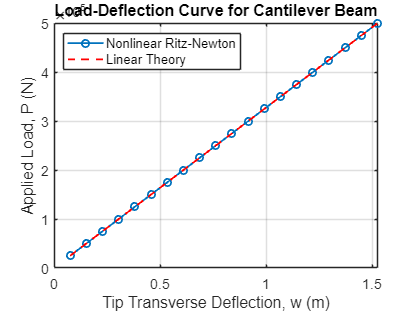

% Calculate tip deflection for each load step
tip_deflections = zeros(1, num_steps);
for i = 1:num_steps
    c2_val = C_history(1, i);
    c3_val = C_history(2, i);
    tip_deflections(i) = c2_val * L_val^2 + c3_val * L_val^3;
end

figure('Name', 'Nonlinear Load-Deflection Curve (Ritz-Newton)');
plot(tip_deflections, load_steps, '-o', 'LineWidth', 1.5, 'DisplayName', 'Nonlinear Ritz-Newton');
hold on;
w_linear = (load_steps * L_val^3) / (3 * E_val * I_val);
plot(w_linear, load_steps, '--r', 'LineWidth', 1.5, 'DisplayName', 'Linear Theory');

grid on;
title('Load-Deflection Curve for Cantilever Beam');
xlabel('Tip Transverse Deflection, w (m)');
ylabel('Applied Load, P (N)');
legend('show', 'Location', 'NorthWest');
set(gca, 'FontSize', 12);


% --- Section 6: Post-Processing and Plotting Final Deflected Shape ---

fprintf('\n--- Plotting Final Deformed Shape ---\n');


--- Plotting Final Deformed Shape ---


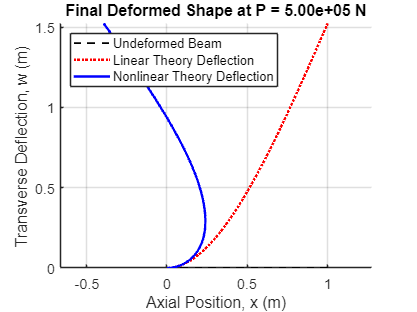


% 1. Create a set of points along the beam length
x_points = linspace(0, L_val, 200);

% 2. Calculate the NONLINEAR deflected shape
% Substitute the final solved coefficients (C) into the symbolic functions
w_sol_final(x) = subs(w_sym, coeffs, C');
u_sol_final(x) = subs(u_sym, coeffs, C');

% Evaluate the nonlinear displacements at each point
w_nonlinear = double(w_sol_final(x_points));
u_nonlinear = double(u_sol_final(x_points));

% The final position in the nonlinear case is (x + u, w)
x_deformed_nonlinear = x_points + u_nonlinear;

% 3. Calculate the LINEAR deflected shape for the final load
P_final = current_load;
w_linear = (P_final * x_points.^2) ./ (6 * E_val * I_val) .* (3 * L_val - x_points);

% 4. Create the plot
figure('Name', 'Final Deformed Shape of the Cantilever Beam');
hold on;

% Plot the original, undeformed beam
plot([0, L_val], [0, 0], 'k--', 'LineWidth', 1.5, 'DisplayName', 'Undeformed Beam');

% Plot the linear deflected shape
plot(x_points, w_linear, 'r:', 'LineWidth', 2, 'DisplayName', 'Linear Theory Deflection');

% Plot the nonlinear deflected shape
plot(x_deformed_nonlinear, w_nonlinear, 'b-', 'LineWidth', 2, 'DisplayName', 'Nonlinear Theory Deflection');

% Add labels, title, and legend
title(sprintf('Final Deformed Shape at P = %.2e N', P_final));
xlabel('Axial Position, x (m)');
ylabel('Transverse Deflection, w (m)');
legend('show', 'Location', 'NorthWest');
grid on;
axis equal; % Use equal scaling to see the true shape
set(gca, 'FontSize', 12);

hold off;